%Req 11
%Approximation
x=[0:0.001:1]

x =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


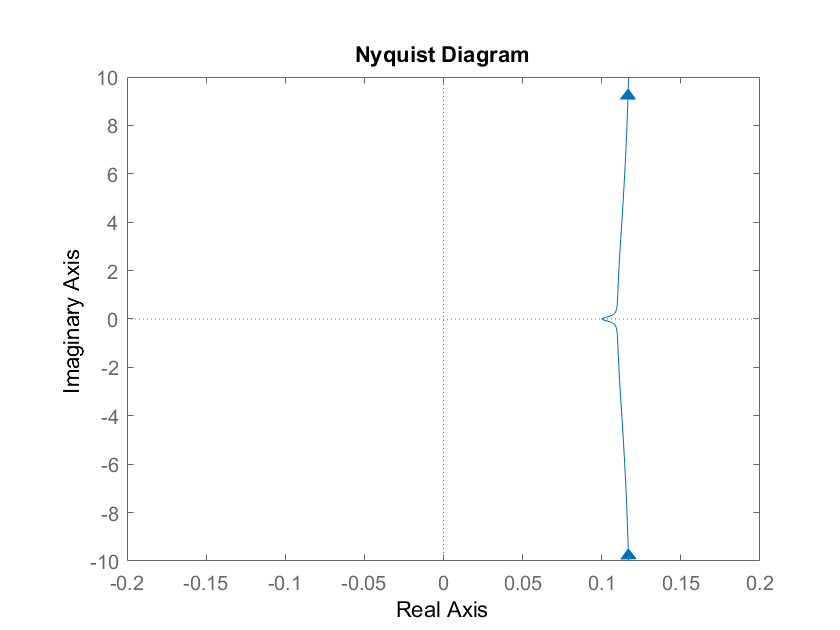

OCV=(2.6+2.35*x-3.75*x.^2+2.5*x.^3);
%5
G1=(OCV(5)-OCV(4))/(0.001);
%50
G2=(OCV(501)-OCV(500))/(0.001);
%95
G3=(OCV(951)-OCV(950))/(0.001);
%Full Gavg
G4=(OCV(1001)-OCV(1))/(1);

%Direct Integration
x1=0.05;
%5
g1 = 2.35 - 2*3.75*x1 + 2.5*3*x1^2;
x2=0.5;
%50
g2=2.35-2*3.75*x2+2.5*3*x2^2;
%90
x3=0.95;
g3=2.35-2*3.75*x3+2.5*3*x3^2;

Q=1;
G=1.1;
R=0.1;
R1=0.01;
R2=0.01;
C1=600;
C2=10;

 A = [0 0 0; 0 -1/(R1*C1) 0; 0 0 -1/(R2*C2)];
 B = [1/Q; 1; 1];
 C = [G 1/C1 1/C2];
 D = [R];
 nyquist(ss(A,B,C,D))
 xlim([-0.2 0.2])

 [num,den] = ss2tf(A,B,C,D)

num =     0.1000    2.2183   11.3833    1.8333


den =     1.0000   10.1667    1.6667         0


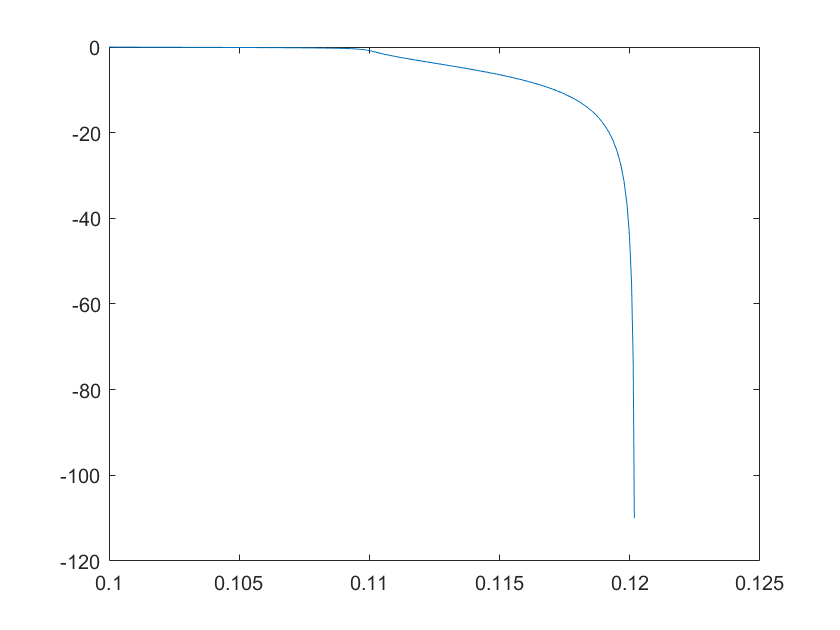

 omega = [0.01:0.005:1000];
 s= sqrt(-1)*omega;
 impedance = (0.1*(s.^3) + 2.2183*(s.^2)+11.3833*s +1.8333)./(1*(s.^3) + 10.1667*(s.^2)+1.6667*s);
 plot(real(impedance),imag(impedance))